*Will Reynolds (will.reynolds@mclaren.com), 2017*

*A large amount of material here is developed from the book 'Fundamentals of Object Tracking' by Challa*

# Kalman Filter Tutorial

This tutorial will first show you the value of the simplest Kalman filter, then walk through the terminology and the equations used for the rest of this tutorial. Once you are comfortable with the general approach of a linear Kalman filter (KF) and familiar with the terms, the next filter algorithms will be introduced and demonstrated in turn.

# Setting Up a Simple Tracking Problem

In order to show the value of the Kalman filter, let's look at a very simple example; a train moving along a straight track at constant velocity. We wish to estimate the states of the train every $\mathrm{dt}$ seconds. I am going to choose the following state vector, $x$, to define the system behaviour at each time step, $k$:

$x_k = \left[ \begin{array}{c}
p_k\\
v_k\\
\end{array} \right]$ , where $p$ is position along the track (m), and $v$ is velocity at which the train is moving (m/s). Given our understanding of the system dynamics, we can say that $p_{k+1} = p_{k} + v_k.\mathrm{dt}$ and $v_{k+1} = v_k$. This can be written as the following matrix algebra equation.


$$x_{k} = F.x_{k-1}=  \left[ \begin{array}{cc}
1 & \mathrm{dt}\\
0 & 1\\
\end{array} \right]. x_{k-1}$$


Now, in almost any situation, our state update will not be this idealised. We will typically have random disturbances acting on our system, which is called **process noise**. For a train, this could be small changes in speed caused by wind buffeting. In this example, we are modelling this noise as a Gaussian random variable, $v_k$, centred around 0m/s, with variance 0.01m/s.


$$x_{k} = F.x_{k-1}=  \left[ \begin{array}{cc}
1 & \mathrm{dt}\\
0 & 1\\
\end{array} \right]. x_{k-1} + v_k$$


The measurement which we have available to us is the position of the train. This measurement, $y_k$, can therefore be written in matrix algebra as:


$$y_k = H.x_k = \left[ \begin{array}{cc}
1 & 0\\
\end{array} \right].  \left[ \begin{array}{c}
p_k\\
v_k\\
\end{array} \right]$$
 

Again, however, it is not likely that a measurement will be perfect. Typically, there will at least be electromagnetic noise acting on the signal. Any noise on the measurement is called, imaginatively, **measurement noise**. In this example, we are modelling this noise as a Gaussian random variable, $w_k$, centred around 0m, with variance 0.1m.

The true initial confitions at time $k=0$ are $x_0 = \left[ \begin{array}{c}
p_0\\
v_0\\
\end{array} \right] = \left[ \begin{array}{c}
0\\
10\\
\end{array} \right]$. However, we are going to start with the erroneous estimate of $\hat{x}_0 = \left[ \begin{array}{c}
0\\
5\\
\end{array} \right]$ to make things more interesting.

# Demonstrating the Value

So, we have now set up the problem. We have a train getting buffeted with wind moving at roughly 10m/s along a straight track with noisy measurements of its position. Let's take a look at tracking its position and velocity. Let's first off look at two extremes of simplistic tracking methods; just using a model, and just using measurements.

Using just the model, we end up being affected by the initial conditions hugely and have no hope of closing the error in position or velocity. 

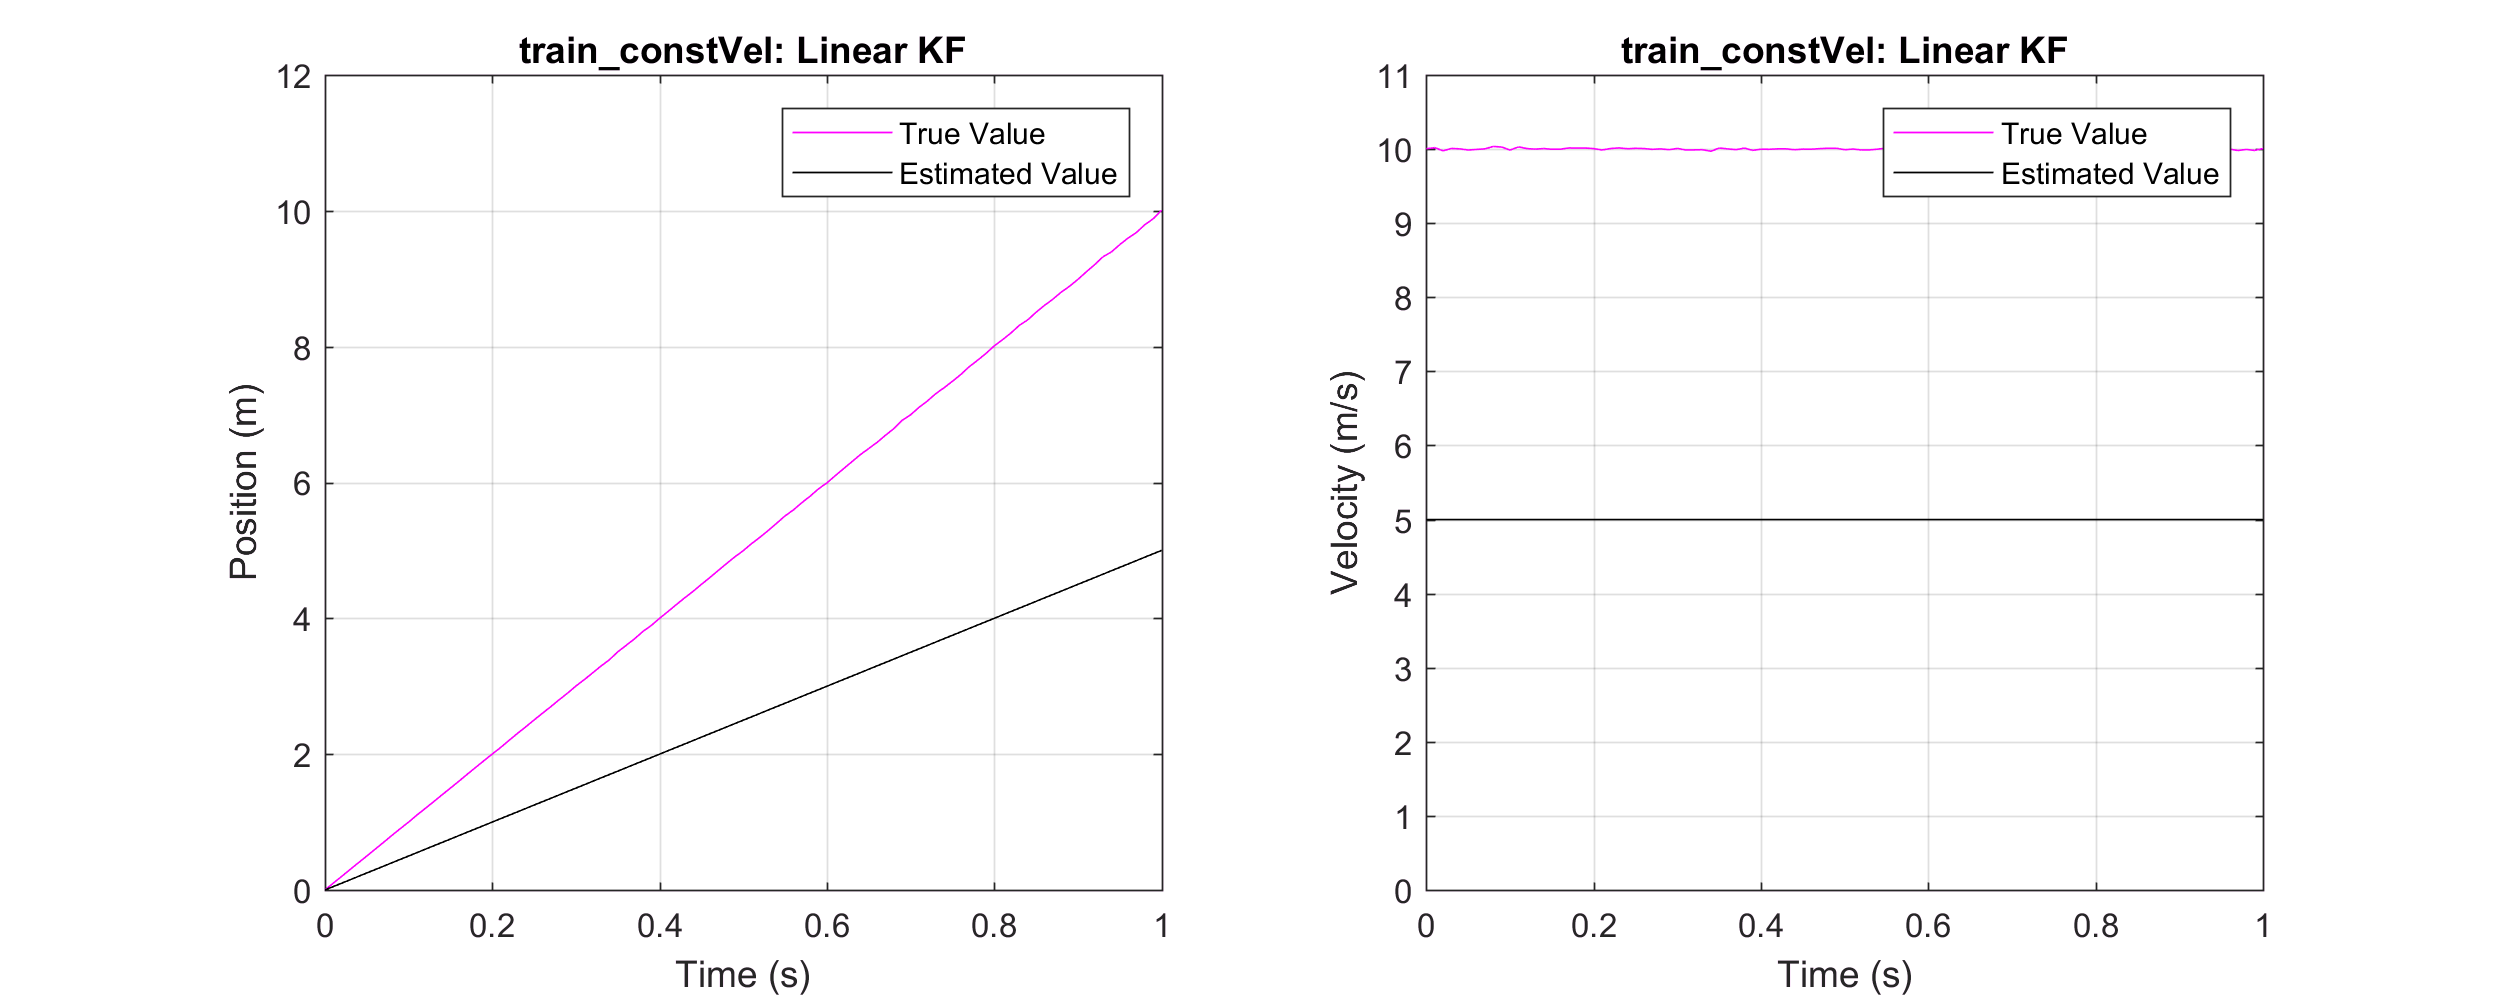

addpath(genpath(pwd))
open('ModelOnly.fig')
set(gcf,'Position',[0 0 1000 400]);

Using just the measurements, we end up at the mercy of the large measurement noise levels and have to infer velocity from this noisy measurement, giving us huge errors in velocity.

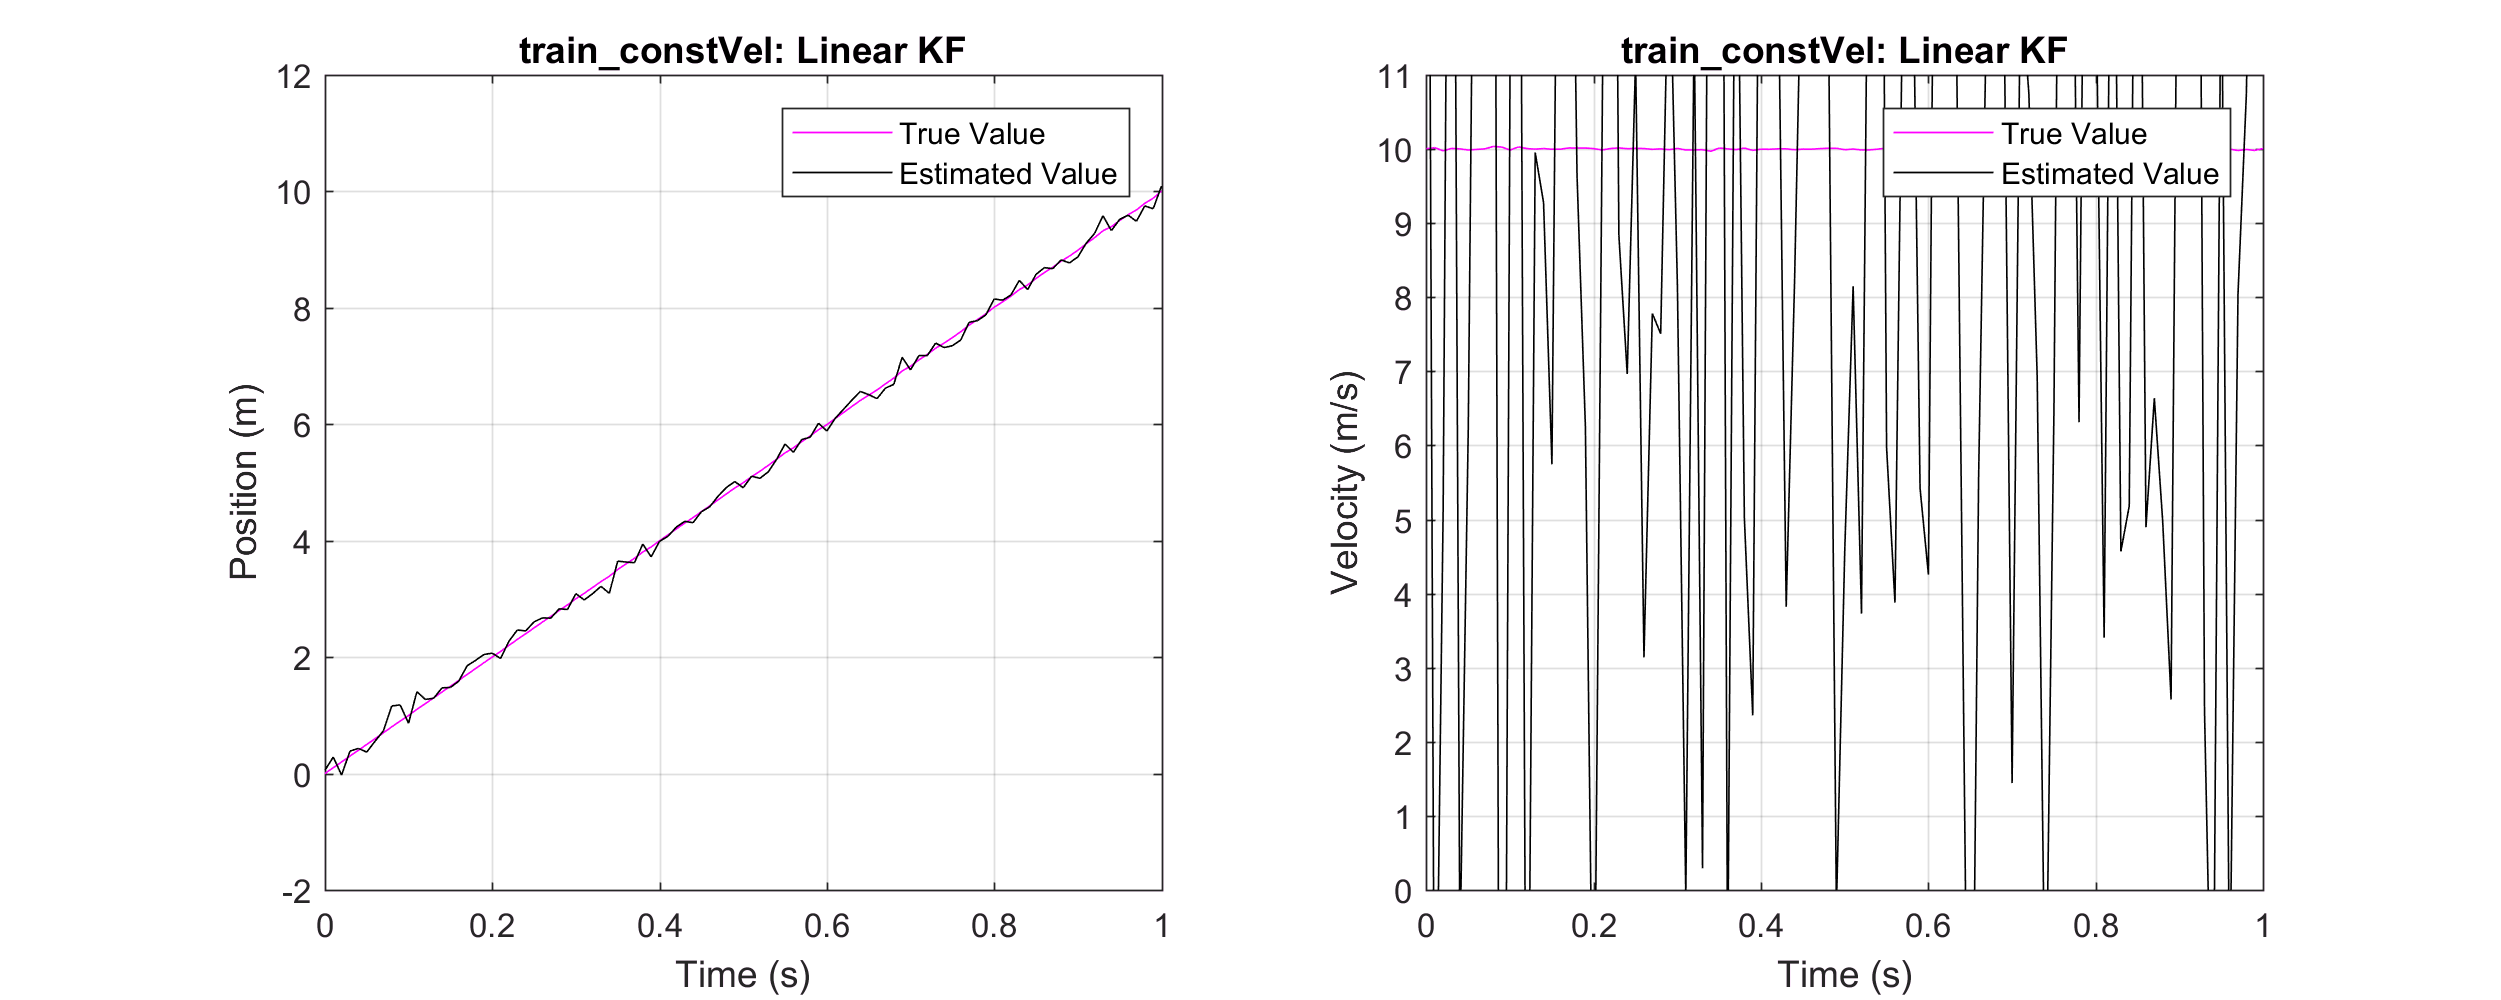

open('MeasurementOnly.fig')
set(gcf,'Position',[0 0 1000 400]);

However, if we implement a simple linear Kalman filter, using our imperfect model of the system and our noisy position measurements, we are able to achieve the following:

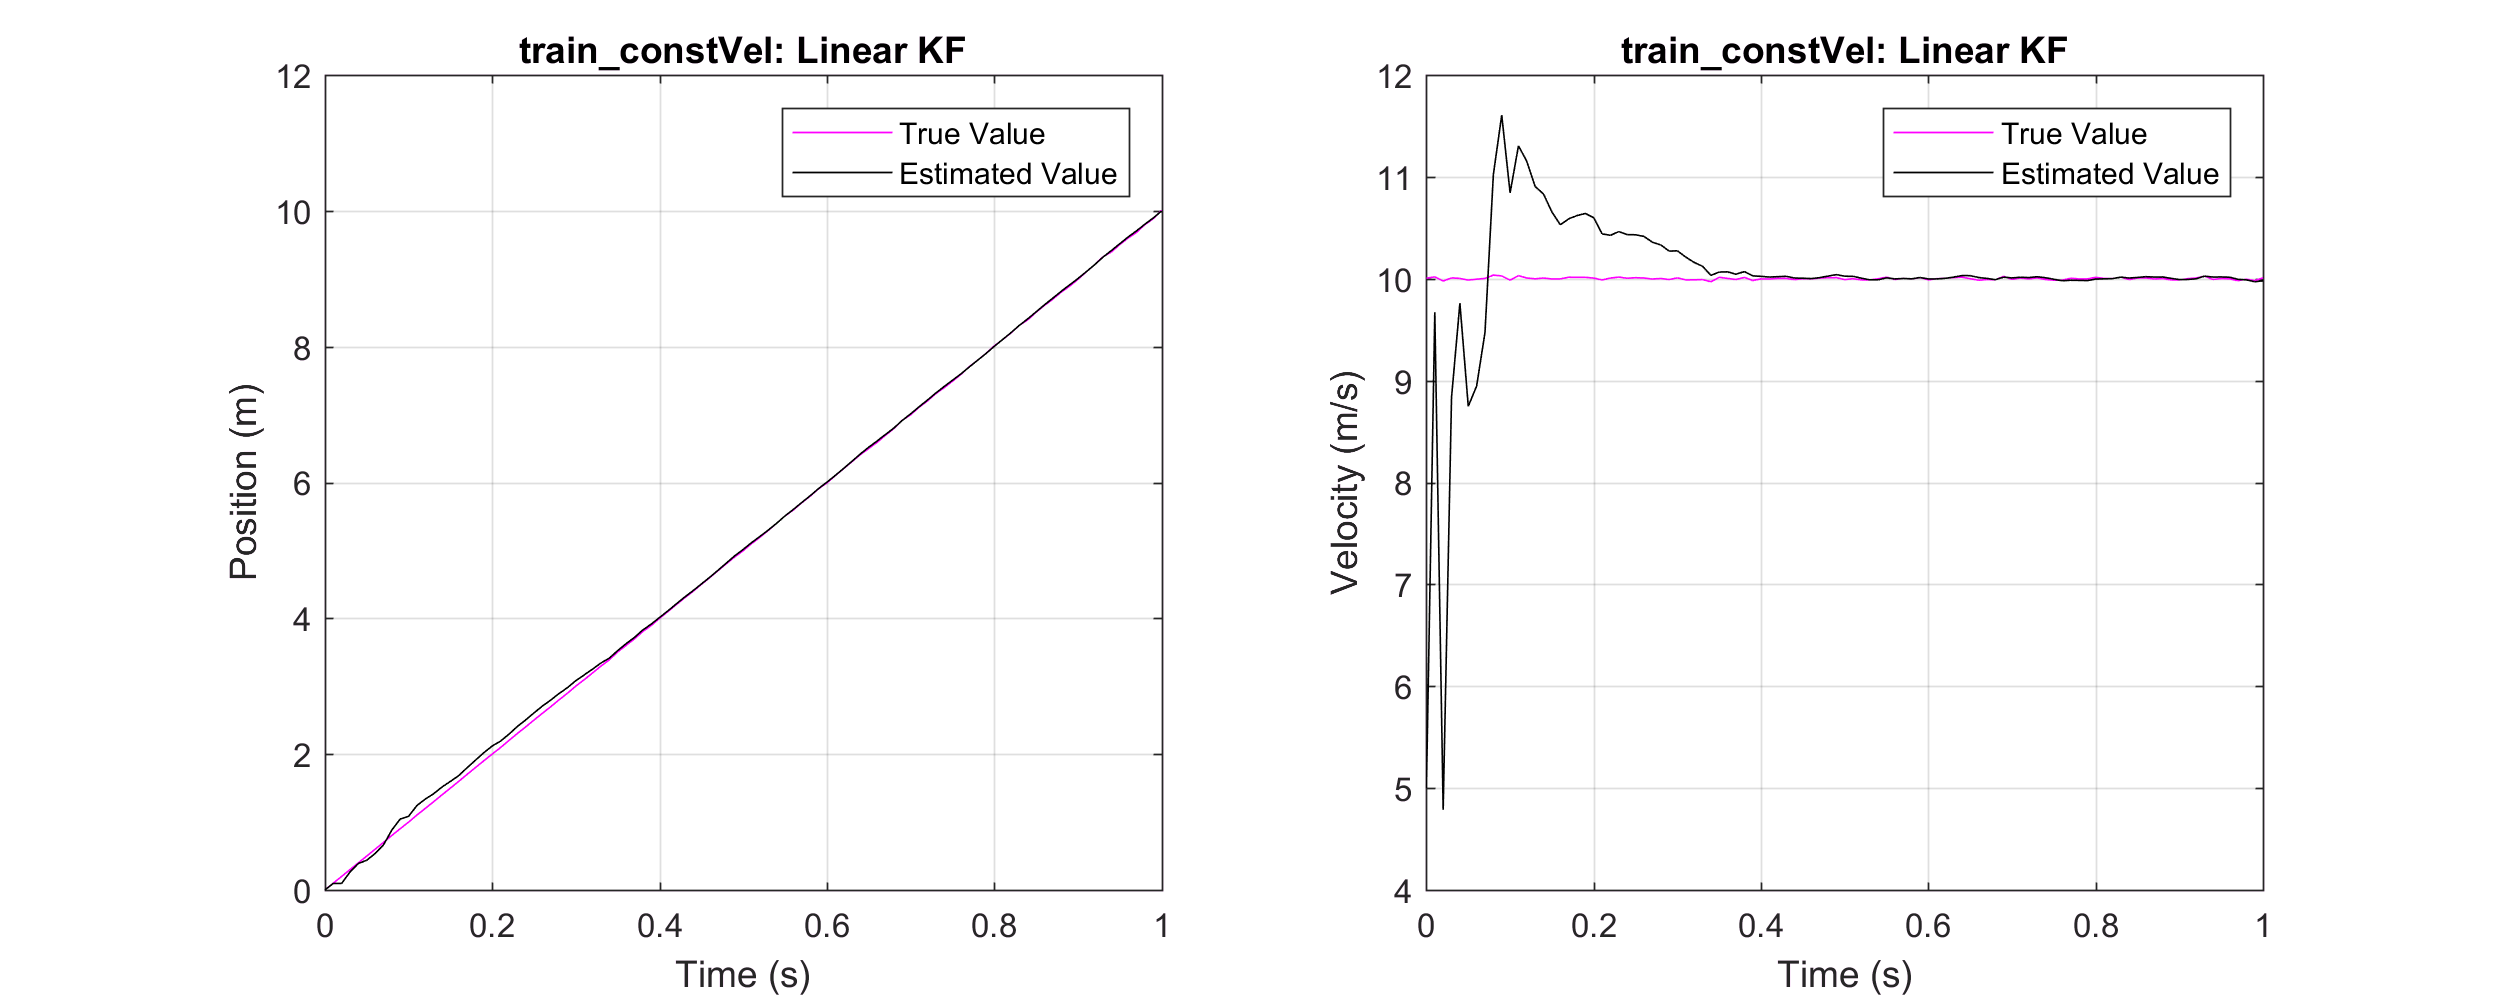

open('LinearKalmanFilter.fig')
set(gcf,'Position',[0 0 1000 400]);

After initially having poor estimates of velocity, due to our erroneous initial condition for velocity, the filter converges at roughly 0.4 seconds, and tracks the states of the system very accurately thereafter. I think this is pretty astonishing, and I hope that this motivates you to want to look under the cover and understand how Kalman filters work and how to use them. This will be the focus of the rest of this tutorial, starting with the linear Kalman filter, which was utilised so effectively in the above example.

# Linear Kalman Filter (KF)

So, we have seen the power of the linear Kalman filter (KF). Let's look at the algorithm, understand the terminology and get to grips with how it all works from one time step to the next. I've presented the equations for the KF below, but for now, skim through them, and let's start off by introducing the terminology:

## Linear Kalman Filter (KF) Equations

**1: Compute the predicted state and covariance matrix:**

Computing the predicted state: $\hat{x}_{k|k-1} = F\hat{x}_{k-1|k-1$ 

Computing the predicted covariance matrix: $P_{k|k-1} = FP_{k-1|k-1}F^T + Q_k$

**2: Compute the predicted measurement, innovation covariance matrix, and Kalman gain:**

Computing the predicted measurement: $\hat{y}_{k|k-1} = Hx_{k|k-1}$

Computing the innovation covariance matrix: $S_k = HP_{k|k-1}H^T + R_k$

Computing the Kalman gain: $K_k = P_{k|k-1}H^TS_K^{-1}$

**3: Compute the posterior mean and covariance matrix:**

Computing the posterior state: $\hat{x}_{k|k} = \hat{x}_{k|k-1}  + K_k(y_k - \hat{y}_{k|k-1})$

Computing the covariance matrix: $P_{k|k} = P_{k|k-1} - K_kH_kP_{k|k-1}$

## Linear Kalman Filter (KF) Terminology

This algorithm may look complex, but it can be easily implemented in only 7 lines of code so don't be put off. Let's demistify it slightly now by understanding some of the terms:

- $x_{k|k-1}$: This is the predicted *state vecto*r for this new time step, $k$,  based on the information from the previous time step, $k-1$. Reread that sentence if you are confused about the subscript notation.

- $\hat{x}_{k|k}$: This is our estimate of the current state $x_{k|k}$, which is the output of the filter. *Calculating this accurately is the purpose of the Kalman Filter*. **During the first time step, this value is specified by us with our best guess for the initial state**. In the example above, we gave it a poor estimate, making it take longer for the state estimate to converge to a good value. In our example, we set an erroneous initial state estimate of: $\hat{x}_{0|0} = \left[ \begin{array}{c}
0\\
5
\end{array} \right]$

- $P$: This is known as the *covariance matrix*, which captures our uncertainty in the state estimate. This, combined with the estimated state give the probability distribution for the state of the system. **During the first time step, this value is specified by us, typically by simply setting the diagonal terms to the magnitude squared of the anticipated error in the corresponding state component**. If we are certain of the position in our example, but believe we could have up to 5 m/s error in velocity, we would set the matrix to be initially: $P_{0|0} = \left[ \begin{array}{cc}
0 & 0\\
0 & 5^2
\end{array} \right]$ 

The job of the Kalman filter is to build an accurate estimate of our system's state at each time step. This is captured by the system state estimate, $\hat{x}_{k|k}$, and the covariance matrix, $P_{k|k}$, which provides the uncertainty around that state. The diagonal terms provide the amount of uncorrelated uncertainty between the states, with the off-diagonal terms giving information as to the correlated uncertainty between the states. Try playing the with these values in the below piece of code and observe how the probability density function changes in the different graph axes.

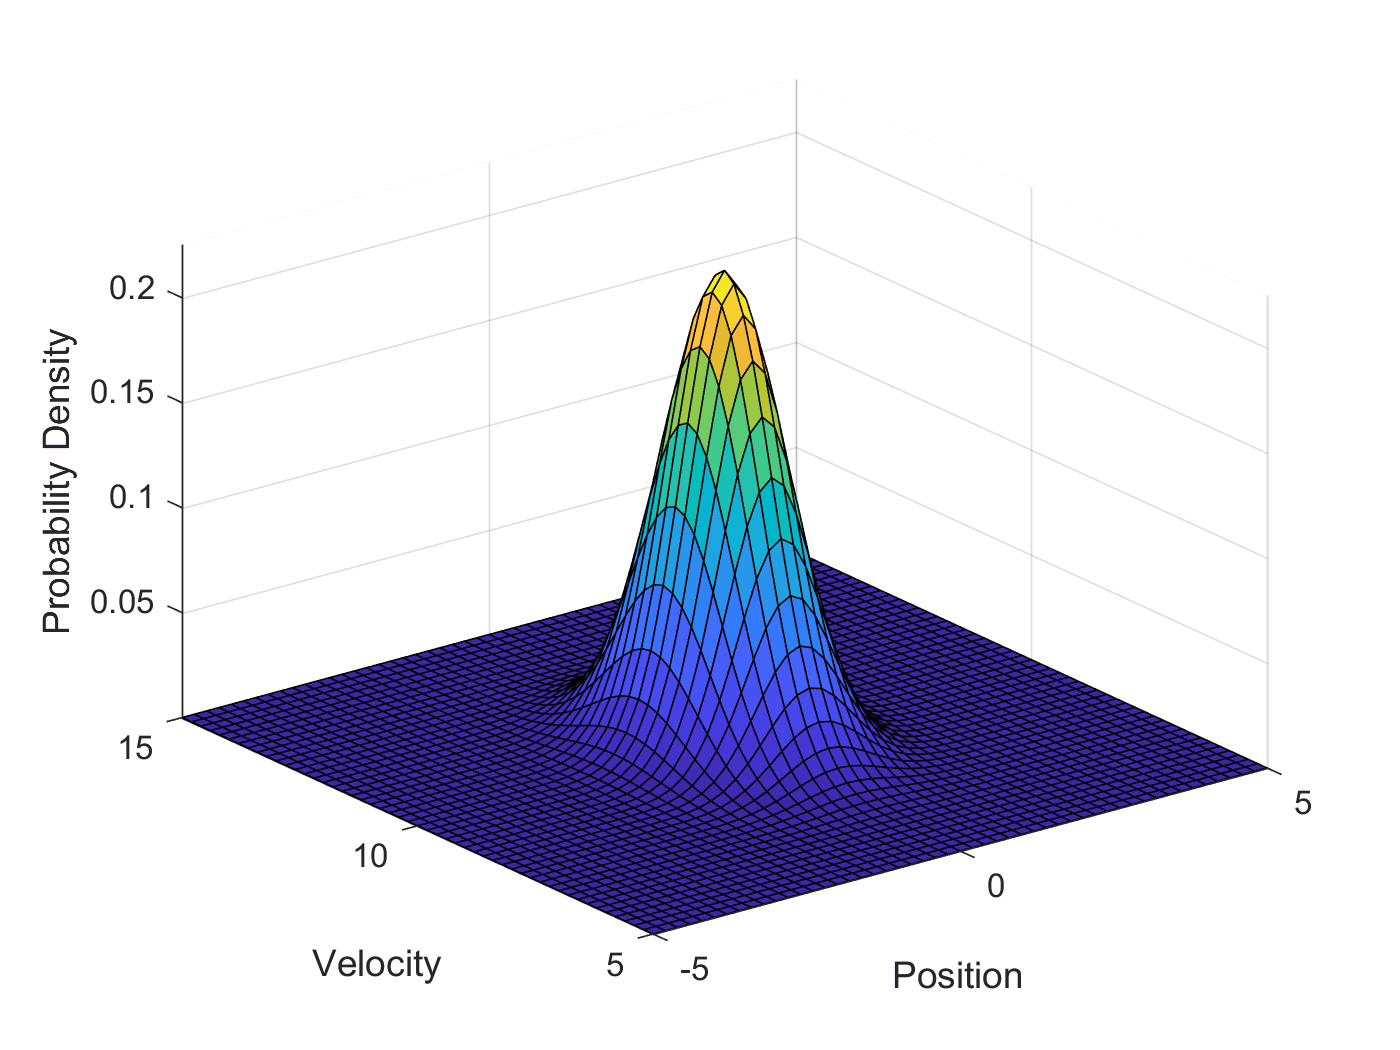

% Specify state mean and covariance parameters
stateMean = [0 10]; % This is our estimate of x
stateCovariance = [.5 0; % This is our matrix P
                    0 1];
% Build grid of points in order to observe Gaussian surface
pos = -5:.2:5; 
vel = 5:.2:15;
[X1,X2] = meshgrid(pos,vel);
% Calculate probabilities at gri points
probability = mvnpdf([X1(:) X2(:)],stateMean,stateCovariance);
probability = reshape(probability,length(vel),length(pos));
% Visualise surface
figure;
surf(pos,vel,probability);
axis([min(pos(:)) max(pos(:)) min(vel(:)) max(vel(:)) min(probability(:)) max(probability(:))])
xlabel('Position'); ylabel('Velocity'); zlabel('Probability Density');

The next parameters to introduce should be the matrices $F$ and $H$, which have already been discussed in our simple example. For a linear Kaman filter to be implemented, it is necessary for the state transistions and measurements to be able to be specified in this simple matrix form.

- $F$: This is known as the* state transitio**n matrix*, which captures our model of the system dynamics. This was introduced in our simple example above, acting as a linear mapping between the current state vector and the next state vector.

- $H$: This is known as the *measurement matrix*, which captures our model of the measurements. This was introduced in our simple example above, acting as a linear mapping between the current state vector and the current measurement.

Next up, we should introduce Q and R in a litte more detail and how we set those up.

- $Q$: This is known as the *process noise covariance matrix*, which captures the amount of uncertainty which is contained in our state transition matrix model. **During the first time step, this value is specified by us with our best guess for the level of process noise, typically by simply setting the diagonal terms to the magnitude squared of the anticipated noise variance in the corresponding state component.**

- $R$: This is known as the measurement* noise covariance matrix*, which captures the amount of uncertainty which is contained in our measurement model. **During the first time step, this value is specified by us with our best guess for the level of measurement noise, typically by simply setting the diagonal terms to the magnitude squared of the anticipated noise variance in the corresponding state component.**

The above terms should now make much more sense, but there are still two more terms to introduce:

- $S$: This is known as the i*nnovation covariance matrix.*

- $K$: This is known as the *Kalman gain.*

In order to explain the meaning behind these terms and get a good understanding of the algorithm formulation, please refer to the excellent website by Tim Babb: [How A Kalman Filter Works in Pictures](http://www.bzarg.com/p/how-a-kalman-filter-works-in-pictures/).

Once you're comfortable with that, let's crack on with looking at the simple code. After setting up our absolute truth in the structure, s, we create our model of the system in the structure, d. From there, we move on each time step and follow the equations above in each of the seven lines of code. And that is the Kalman filter. If you can specify an accurate **linear** system behaviour and measurement with $F$ and $H$, and give an initial estimate of $\hat{x}$, $P$, $Q$, and $R$, you have all the ingredients to create a Kalman filter (KF).

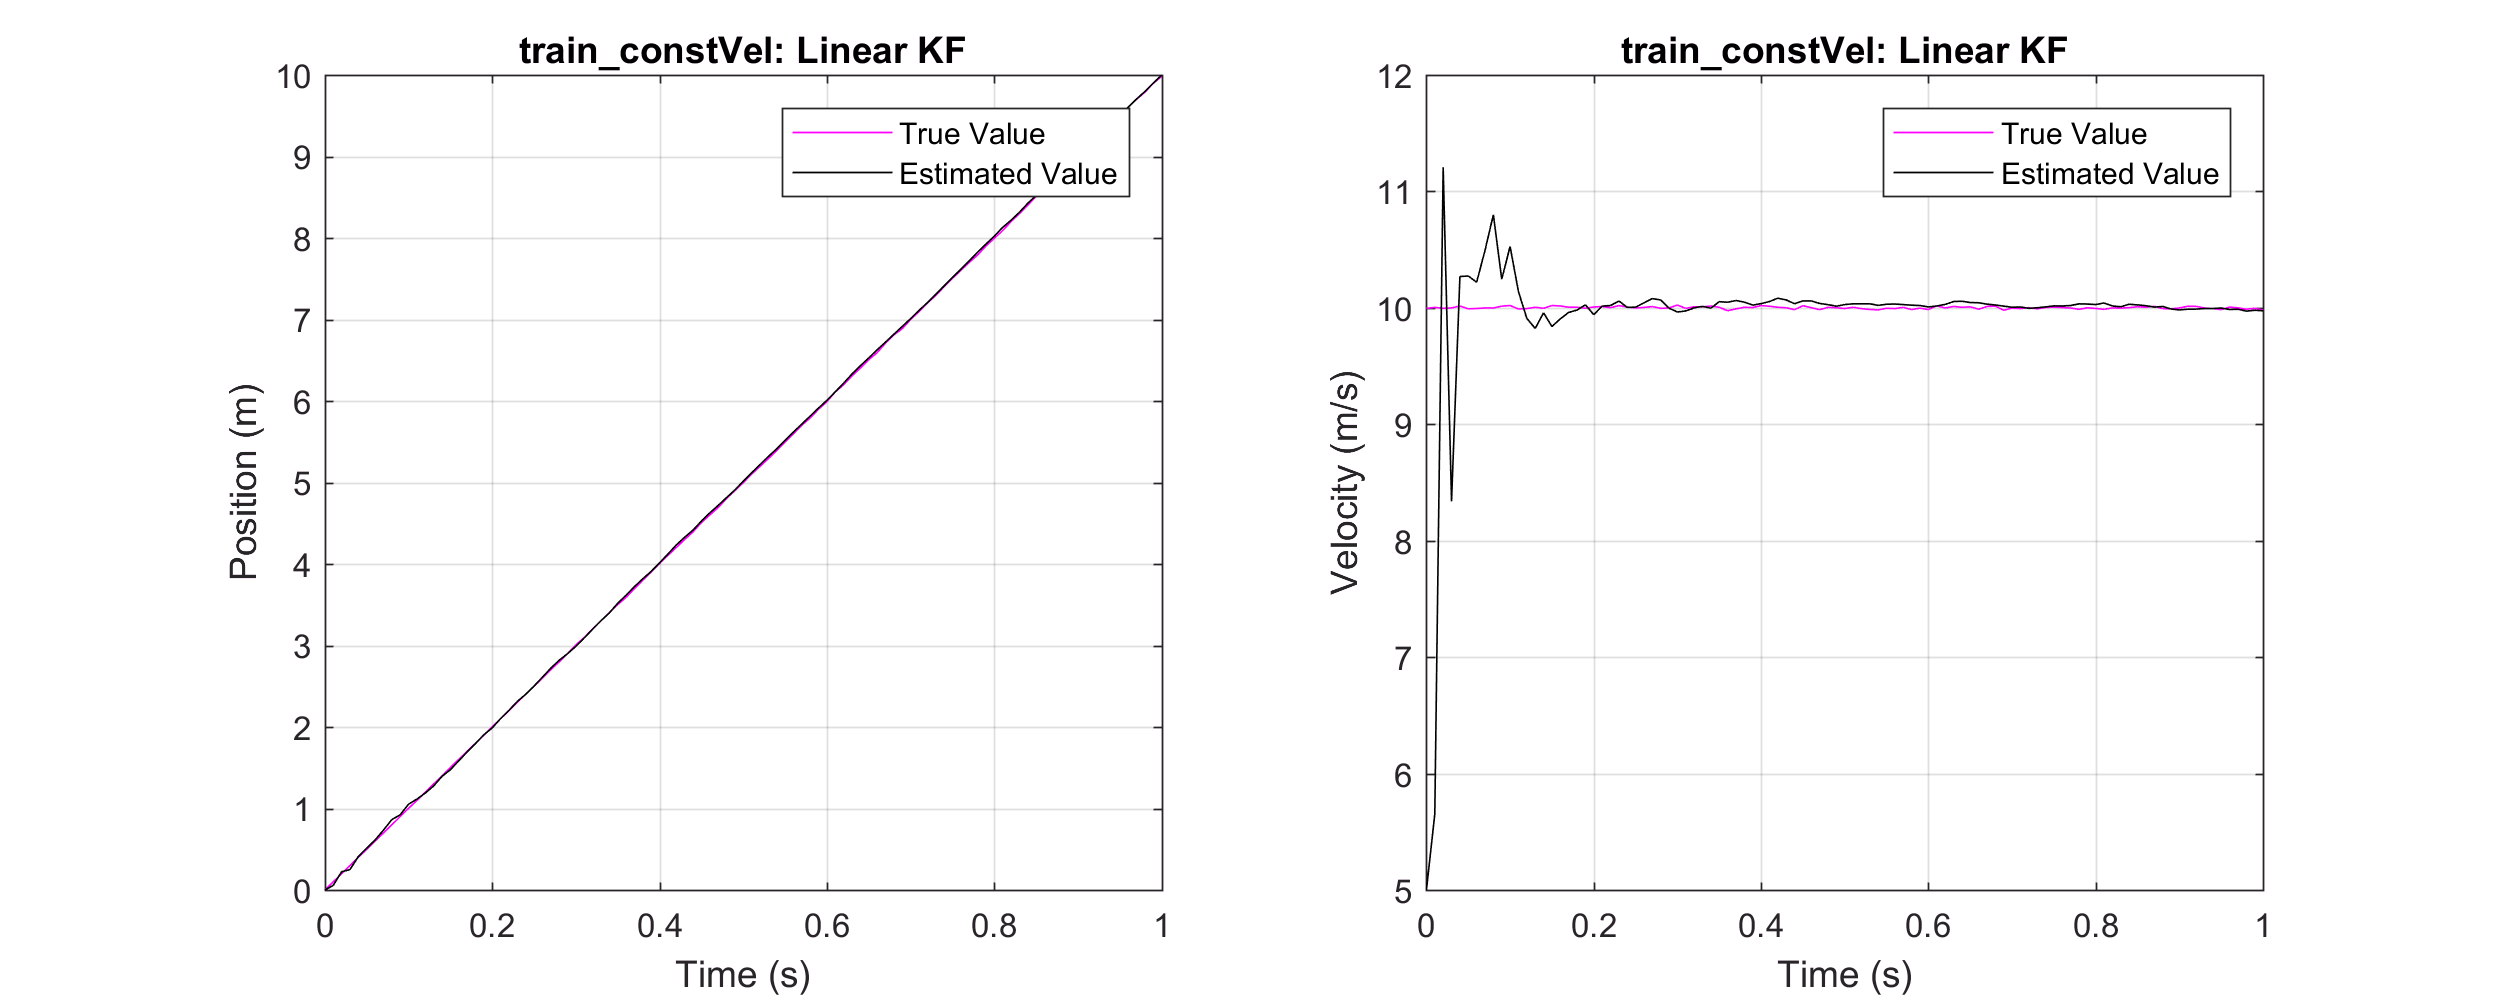

%% Set General Parameters %%%%%%%%%%%%%
NSamples=100; % Number of sample steps to simulate over
dt = 0.01; % Time step between samples, s

%% Ground Truth & Model %%%%%%%%%%%%%%%
s = train_constVel(NSamples,dt); % Set up a system of a train travelling at a constant velocity
d = model_train_constVelKF(s,dt); % Set up a KF model for the system

%% Linear Kalman Filter %%%%%%%%%%%%%%%
for k=2:NSamples+1
    % Compute the predicted mean, d.X1
    d.X1 = d.F * d.X(:,k-1);
    % Compute the predicted covariance matrix, d.P1
    d.P1 = (d.F * d.P * d.F') + d.Q;
    
    % Compute the predicted measurement, d.Y1
    d.Y1 = d.H * d.X1;
    % Compute the innovation covariance matrix, d.S
    S = (d.H * d.P1 * d.H') + d.R;
    % Compute the Kalman gain (K large -> more weight goes to measurement)
    K = (d.P1 * d.H' / S);
    
    % Compute the posterior mean, d.X
    d.X(:,k) = d.X1 + (K * (s.Y(:,k) - d.Y1));
    % Compute the covariance matrix, d.P
    d.P = d.P1 - (K * d.H * d.P1);
end

%% Plot resulting graphs %%%%%%%%%%%%%%
figure;
for i = 1:s.NState
    subplot(1,2,i);
    plot(s.t,s.X(i,:),'m');
    hold on; grid on;
    plot(s.t,d.X(i,:),'k');
    title(['Estimation Results: ' s.stateString{i}]);
    xlabel(s.tString);
    ylabel(s.stateString{i});
    legend('True Value','Estimated Value');
    t = title([s.modelString ': ' d.typeString]);
    set(t, 'Interpreter', 'none');
end
set(gcf,'Position',[0 0 1000 400]);

Take some time now to play around with the model and initialisation of the matrices in this example, but tweaking numbers in the function *model_train_constVelKF. *Specifically dedicating time to playing with the initial value of $\hat{x}$ and $P$ and observe the amount of time which the filter takes to converge.

Let's close off our analysis of the simple linear Kalman filter (KF). The Kalman filter has the following characteristics:

- It is very computationally light. It consists of simple matrix algebra. Therefore, as long as the number of states is small enough, this code should run on even a small microcontroller.

- Let's consider the systems which can be modelled with this KF. This filter can only be used on **linear systems**. If it is not possible to specify the system behaviour as $x_{k} = F.x_{k-1}$ with $F$ being a matrix containing purely numerical elements, then this type of Kalman filter is not appropriate for your application. The same is true for the matrix $H$.

- For this filter to work most effectively, the measurement noise, process noise, and posterior state density must be white, Gaussian noise. The further away from this idealisation that the real system gets, the worse the performance will be.

What tends to be the biggest problem with real life applications is that we regularly have to deal with non-linearity. If we still have Gaussian noise profiles but we have a non-linear system, attention should be turned to the Extended Kalman Filter (EKF) and Unscented Kalman Filter (UKF).

# Extended Kalman Filter (EKF)

The Extended Kalman Filter is a wonderfully-logical next step for the Kalman filter when have to start dealing with non-linearity in our system. The underlying method with the Extended Kalman Filter is to linearise our system at each time step and then use the regular Kalman Filter methdology. And that's it. The equations below look very similar to the KF equations as a result:

## Extended Kalman Filter (EKF) Equations

**1: Compute the Jacobian of **$f$ **at **$\hat{x}_{k-1|k-1}$:

Computing the Jacobian: $F_k = \bigtriangledown_{x^T} f(x)|_{x=\hat{x}_{k-1|k-1}$

**2: Compute the predicted state and covariance matrix:**

Computing the predicted state: $\hat{x}_{k|k-1} = f(\hat{x}_{k-1|k-1})$ 

Computing the predicted covariance matrix: $P_{k|k-1} = FP_{k-1|k-1}F^T + Q_k$

**3: Compute the Jacobian of **$h$ at $\hat{x}_{k|k-1}$:

Computing the Jacobian: $H_k = \bigtriangledown_{x^T} h(x)|_{x=\hat{x}_{k|k-1}$

**4: Compute the predicted measurement, innovation covariance matrix, and Kalman gain:**

Computing the predicted measurement: $\hat{y}_{k|k-1} = h(x_{k|k-1})$

Computing the innovation covariance matrix: $S_k = HP_{k|k-1}H^T + R_k$

Computing the Kalman gain: $K_k = P_{k|k-1}H^TS_K^{-1}$

**5: Compute the posterior mean and covariance matrix:**

Computing the posterior state: $\hat{x}_{k|k} = \hat{x}_{k|k-1}  + K_k(y_k - \hat{y}_{k|k-1})$

Computing the covariance matrix: $P_{k|k} = P_{k|k-1} - K_kH_kP_{k|k-1}$

## Extended Kalman Filter (EKF) Terminology

There are three terms which should be introduced here:

- $f$: This is known as the* state transitio**n function.* This function captures our model of the non-linear system dynamics, and acts as a mapping between the current state vector and the next state vector. 

- $h$: This is known as the *measurement function*. This function captures our model of the non-linear measurement, and acts as a mapping between the current state vector and the measurement. If you can specify $f$ and $h$ algebraically, then you can use the Extended Kalman Filter.

- $\bigtriangledown$: This is known as the Jacobian operator. By using a Jacobian operator on a function at a specific point, we can linearise the function about that operating point at each point in time, allowing us to follow the traditional Kalman filter equations for the rest of the algorithm. If you are unfamiliar with the Jacobian operator and would like to know more, please refer to the following video: [The Jacobian Matrix (YouTube)](https://www.youtube.com/watch?v=bohL918kXQk).

So, the EKF purely consists of a linearisation step within the algorithm, for both the system prediction model and the measurement model. And then it continues along the same as a KF. Simple as that. So let's set up a new example to illustrate this in action.

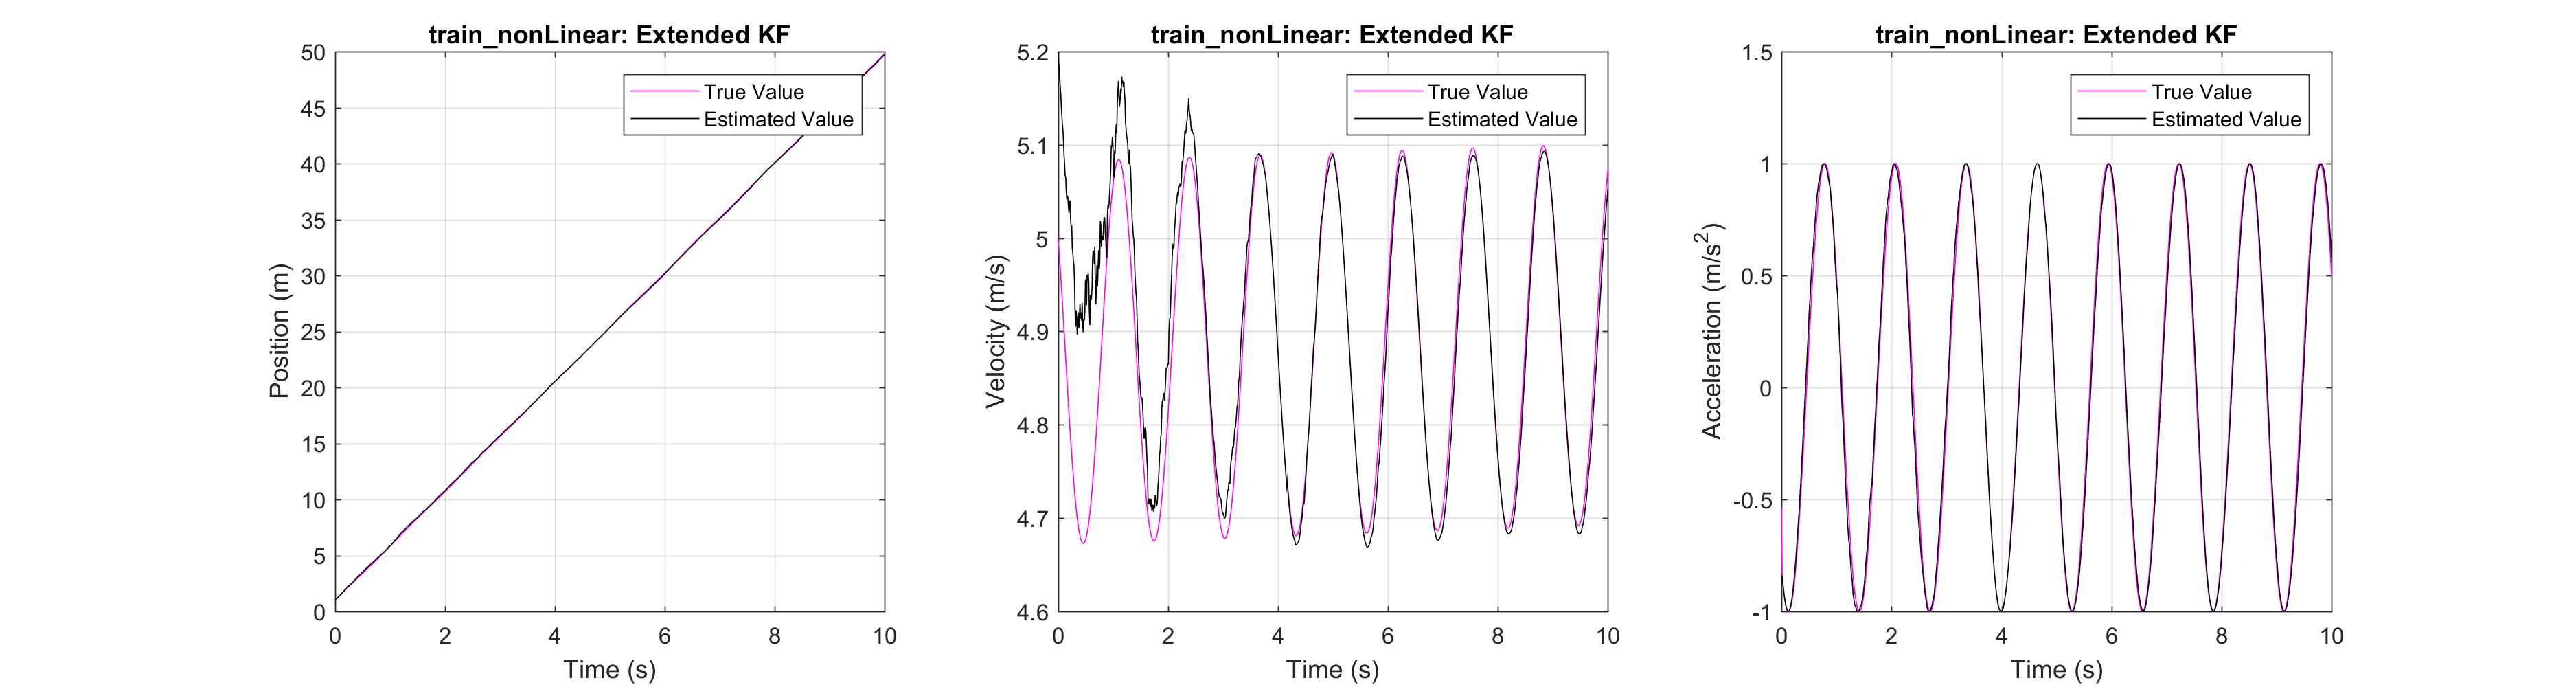

%% Set General Parameters %%%%%%%%%%%%%
NSamples=1000; % Number of sample steps to simulate over
dt = 0.01; % Time step between samples, s

%% Ground Truth & Model %%%%%%%%%%%%%%%
s = train_nonLinear(NSamples,dt); % Set up a system of a train constrained to the origin by a non-linear spring
d = model_train_nonLinearEKF(s,dt); % Set up an EKF model for the system

%% Extended Kalman Filter %%%%%%%%%%%%%
for k=2:NSamples+1
    % Compute the Jacobian to obtain the linearised state transition matrix
    d.F = double(subs(d.J,d.X(1,k-1)));
    
    % Compute the predicted mean with the non-linear model equations, d.X1
    d.X1 = d.predCalc(d.X(:,k-1),dt);
    % Compute the predicted covariance matrix, d.P1
    d.P1 = (d.F * d.P * d.F') + d.Q;

    % Compute the Jacobian to obtain the linearised measurement matrix
    d.H = double(subs(d.L,d.X(1,k-1)));
    
    % Compute the predicted measurement, d.Y1
    d.Y1 = d.measCalc(d.X1,dt);
    % Compute the innovation covariance matrix, d.S
    S = (d.H * d.P1 * d.H') + d.R;
    % Compute the Kalman gain (K large -> more weight goes to measurement)
    K = (d.P1 * d.H' / S);

    % Compute the posterior mean, d.X
    d.X(:,k) = d.X1 + (K * (s.Y(:,k) - d.Y1));
    % Compute the covariance matrix, d.P
    d.P = d.P1 - (K * d.H * d.P1);
end

%% Plot resulting graphs %%%%%%%%%%%%%%
figure;
for i = 1:s.NState
    subplot(1,3,i);
    plot(s.t,s.X(i,:),'m');
    hold on; grid on;
    plot(s.t,d.X(i,:),'k');
    title(['Estimation Results: ' s.stateString{i}]);
    xlabel(s.tString);
    ylabel(s.stateString{i});
    legend('True Value','Estimated Value');
    t = title([s.modelString ': ' d.typeString]);
    set(t, 'Interpreter', 'none');
end
set(gcf,'Position',[0 0 1500 400]);

So, here we can see that, as we have initialised the velocity incorrectly in our filter (5.2 m/s instead of 5.0 m/s), the filter takes some time to converge, but appears to be trending nicely along with the true value from around 6 seconds onwards. Take some time to dig into the code here and understand how it works.

The EKF is a simple and elegant non-linear filtering approximation which performs well in many applications. However, there are flaws in the use of the EKF. the EKF is prone to divergence when the posterior mean approximation is significantly different from the true state. This is primarily caused by an 'optimistic approximation' of the posterior covariance matrix [Challa, Fudamentals of Object Tracking]. In essence, the EKF is prone to diverging which makes it unsuitable for safety-rated applications or any applications which need to run robustly for any long duration.

Let's close off our analysis of the Extended Kalman filter (KF). The Extended Kalman Filter has the following characteristics:

- It is of medium computational complexity. It consists of simple matrix algebra, but the computations of the Jacobian matrices are non-trivial in most cases. In some cases, this could easily prevent an EKF running on an embedded device.

- This filter can be used on **non-linear systems**, which makes it more generally useful than the KF.

- For this filter to work most effectively, the measurement noise, process noise, and posterior state density must still be white, Gaussian noise. The further away from this idealisation that the real system gets, the worse the performance will be. This is the same as for the KF.

If we're looking for a Kalman filter with similar computational complexity, but faster convergence and greater ability to handle non-linearities, we should turn our attention to the Unscented Kalman Filter (UKF). This filter is the standard algorithm for GPS tracking, but is certainly not a foolproof method; we still need to watch out for divergence effects and handle its implementation carefully.

# Unscented Kalman Filter (UKF)

The Unscented Kalman Filter is a less obvious next step for the Kalman filter. Rather than linearising the system model and measurement model about the current operating point, the Unscented Kalman Filter instead linearises the state mean and covariance about the operating point. This is the core of the Unscented Transform (named after a can of deodorant) and the Unscented Kalman Filter. The mathematics for this particular filter may seem awkward, but it is actually relatively transparent and will become more obvious as we move into the point mass filter and particle filter in the last couple of sections of this tutorial.

## Unscented Kalman Filter (UKF) Equations

**1: Determine sigma points **$\chi^1_{k-1}, .\;.\;. \;, \chi^s_{k-1} $ **and weights** $w^1,\;.\;.\;.\;,w^s$ **to match a mean** $\hat{x}_{k-1|k-1}$ **and covariance matrix** $P_{k-1|k-1}$.

**2: Compute the transformed sigma points **$\chi^i_k = f(\chi^i_{k-1}) ,\; i = 1,\;.\;.\;.\;,s$.

**3: Compute the predicted state statistics**:

Predicted mean state: $\hat{x}_{k|k-1} = \sum\limits_{i=1}^{s} w^i\chi^i_k$

Predicted covariance: $P_{k|k-1} = Q_k + \sum\limits_{i=1}^s w^i (\chi^i_k - \hat{x}_{k|k-1})(\chi^i_k - \hat{x}_{k|k-1})^T$

**4: Determine sigma points **$\chi^1_{k-1}, .\;.\;. \;, \chi^s_{k-1} $ **and weights** $w^1,\;.\;.\;.\;,w^s$ **to match a mean** $\hat{x}_{k
|k-1}$ **and covariance matrix** $P_{k|k-1}$.

**5: Compute the transformed sigma points **$\gamma^i_k = h(\chi^i_{k}) ,\; i = 1,\;.\;.\;.\;,s$.

**6: Compute the predicted measurement statistics:**

Predicted measurement: $\hat{y}_{k|k-1} = \sum\limits_{i=1}^sw^i\gamma_k^i$

Innovation covariance matrix: $S_k = R_k + \sum\limits_{i-1}^s w^i (\gamma^i_k - \hat{y}_{k|k-1})(\gamma^i_k - \hat{y}_{k|k-1})^T$

Cross-correlation/Kalman Gain: $K_k = \sum\limits_{i=1}^s w^i (\chi^i_k - \hat{x}_{k|k-1})(\gamma^i_k - \hat{y}_{k|k-1})^T$ 

**7: Compute the posterior mean and covariance matrix:**

Posterior mean: $\hat{x}_{k|k} = \hat{x}_{k|k-1} + K_kS_k^{-1}(y_k - \hat{y}_{k|k-1})$

Covariance matrix: $P_{k|k} = P_{k|k-1} - K_kS_k^{-1}K_k^T$

## Unscented Kalman Filter (UKF) Terminology & Flow

Let's walk through some of the unfamiliar terms in the above equations and get our heads around the UKF approach by walking slowly through each step:

- $\chi^1_{k-1}, .\;.\;. \;, \chi^s_{k-1} $: This set of variables is our set of *sigma points*. They are simply a set of states placed deterministically around the state mean. There are several methods of selecting these states or *sigma points*, but it is very common to use the original method, proposed by Julier et al. (2000), and select $2n+1$ points. In our example shown below, we have a probability density function for a problem with 2 states ($n=2$), akin to the Gaussian which we played with earlier in the tutorial, and we have 5 *sigma points* selected. One point is selected at the estimated state mean, with the others distributed around the surface, depending on the sampling strategy used. For more information on this sampling strategy, refer to the Julier paper: [A New Method for the Nonlinear Transformation of Means and Covariances in Filters and Estimators](http://www.mne.psu.edu/ray/me577/me577PF_Julier2000.pdf)

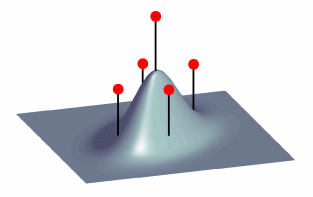

-  $w^1,\;.\;.\;.\;,w^s$: This set of variables is our set of *weights*, each of which corresponds to one of our sigma points. These weights can be thought of as the probability assocated with that sigma point state. So, in the first step of the algorithm, we must select our sigma points and *weights* such that the posterior mean and covariance from the previous time step are captured.

- Step 2 is very simple; we pass each of our sigma points, $\chi^1_{k-1}, .\;.\;. \;, \chi^s_{k-1} $, through our non-linear *state transition function*, $f$, and generate our updates set of sigma points, $\chi^1_{k}, .\;.\;. \;, \chi^s_{k} $. This is illustrated in the simple diagram below. We now have our predicted set of potential states based on our sample set of sigma points.

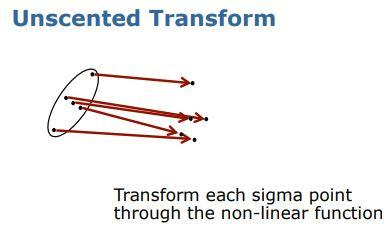

- The next step, Step 3, is where we recompute the state mean and covariance based on these predicted sigma points. The equations here are pretty transparent, so with some thought should be understood by yourself.

- In Step 4, the sigma points are resampled based on the new predicted state statistics.

- Step 5 is also very simple; we pass each of our sigma points, $\chi^1_{k}, .\;.\;. \;, \chi^s_{k} $, through our non-linear *measurement function*, $h$, and generate our updates set of sigma points, $\gamma^1_{k}, .\;.\;. \;, \gamma^s_{k} $. This is illustrated in the simple diagram above. We now have our predicted set of potential measurements based on our sample set of sigma points.

- So, now we have our update step in Step 6. The estimated measurement calculation, $\hat{y}_{k|k-1}$ is trivial, and the innovation covariance matrix, $S_k$, is a replica of our predicted covariance matrix from Step 3. The only point which it is worth dwelling on is our calculation of the Kalman gain, $K_k$. This Kalman gain is, in essence, the same as for the linear Kalman filter. It captures the weighting which should be given to the measurement information. Therefore, $K_k$ is calculated as the weighted cross-correlation between the predicted state information and the updated measurement information. The value of this calculation becomes transparent in Step 7.

- Step 7 is where we calculate the new time step's state estimate and covariance. This shows the value of the Kalman gain. Each term consists of the predicted term plus, essentially, a weighted amount of the information from the measurements. The less reliable the measurements are, the lower $K_k$ will be, hence the lower the reliance on that souce of information will be.

So, there we have the foundation of the Unscented Kalman Filter (UKF). We place points about the current state estimate and put them through our non-linear system model. We then recalculate the state estimate and covariance, place new points, and put them through our measurement model. We then calculate the amount of weight which we should place on the measurement information, and updated our predicted states with our measurement information.

This is the essence of an Unscented Kalman Filter and is also the same fundamental process behind the Point Mass Filter (PMF) and the Particle Filter (PF). So let's see the code in action on a non-linear problem.

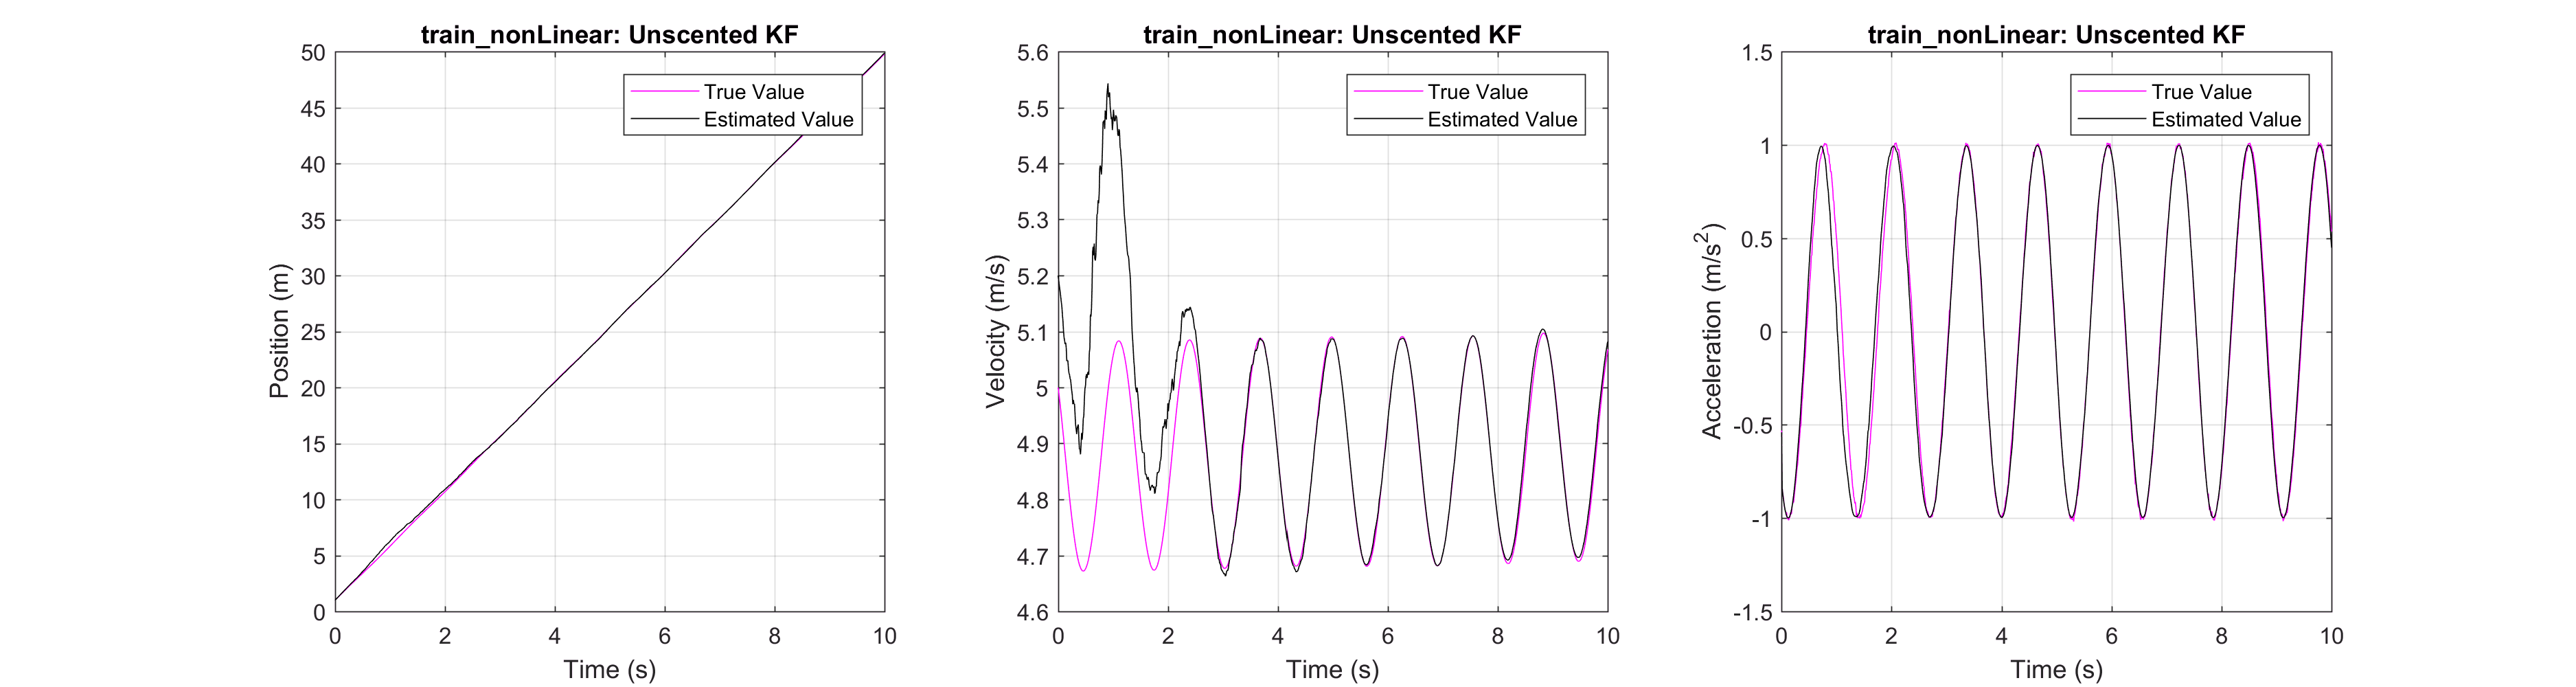

%% Set General Parameters %%%%%%%%%%%%%
NSamples=1000; % Number of sample steps to simulate over
dt = 0.01; % Time step between samples, s

%% Ground Truth & Model %%%%%%%%%%%%%%%
s = train_nonLinear(NSamples,dt); % Set up a system of a train constrained to the origin by a non-linear spring
d = model_train_nonLinearUKF(s,dt); % Set up a UKF model for the system

%% Unscented Kalman Filter %%%%%%%%%%%%%
d.Xpred = zeros(size(d.X));
for k=2:NSamples+1
    % UKF prediction step
    [d.Xpred(:,k),d.P] = ukf_predict1(d.X(:,k-1),d.P,d.predModel,d.Q,d.f_param,d.alpha,d.beta,d.kappa);
    % UKF update step
    [d.X(:,k),d.P] = ukf_update1(d.Xpred(:,k),d.P,s.Y(:,k),d.measModel,d.R,d.h_param,d.alpha,d.beta,d.kappa);
end

%% Plot resulting graphs %%%%%%%%%%%%%%
figure;
for i = 1:s.NState
    subplot(1,3,i);
    plot(s.t,s.X(i,:),'m');
    hold on; grid on;
    plot(s.t,d.X(i,:),'k');
    title(['Estimation Results: ' s.stateString{i}]);
    xlabel(s.tString);
    ylabel(s.stateString{i});
    legend('True Value','Estimated Value');
    t = title([s.modelString ': ' d.typeString]);
    set(t, 'Interpreter', 'none');
end
set(gcf,'Position',[0 0 1500 400]);

The Unscented Kalman Filter has been implemented in this example in a slightly less transparent way than the rest of the examples in this tutorial. It could be written almost as simply as the rest of the examples given more time.

We can see that the UKF shows a similar behaviour in this example to the EKF algorithm. If a more non-linear system is modelled, the power of the Unscented Kalman Filter would be apparent. The UKF is a relatively simple non-linear system method which is pretty much an industry standard for non-linear Kalman filtering. However, when the covariance matrix is being calculated, there is an operation called Cholesky factorisation, which requires that the matrices in this operation are positive definite. If this is not the case, the filter will 'explode'. On paper, this shouldn't happen, but due to numerical error in the computation, this will inevitably happen at some point in time as the errors build up. There are several ways to mitigate this to an extent, but none of them foolproof. As a result, a good step is to keep an eye on the matrices going into this operation and reset them to sensible values if they become non-positive-definite.

Let's close off our analysis of the Unscented Kalman filter (UKF). The Unscented Kalman Filter has the following characteristics:

- It is of medium computational complexity. It consists of simple matrix algebra, but the factorisation operations contained within it are non-trivial. In some cases, this could easily prevent a UKF running on an embedded device.

- This filter can be used on **non-linear systems**, which makes it more generally useful than the KF, and is able to cope with non-linearity better than an EKF.

- For this filter to work most effectively, the measurement noise, process noise, and posterior state density must still be white, Gaussian noise. The further away from this idealisation that the real system gets, the worse the performance will be. This is the same as for the KF.

So, we've now taken a look at two algorithms which can be used if we remove the 'crutch' of a linear system. But let us say that we have non-Gaussian noise. A good example of this might be where we are measuring position using a laser pointing at an object. The device may understimate the distance if a bit of dust moves between the laser diode and the object, but it will never overestimate the position. This might need to be modelled as a one-sided Gaussian. Then we move into the world of Point Mass Filters and Particle Filters, where the system and measurement model need not be linear, the measurement and process noise need not be Gaussian, and the posterior density need not be Gaussian either.

# Point Mass Filter (PMF)

The Point Mass Filter and Particle Filter are very similar in design. The Point Mass Filter is the baby of the two so let's look at that first. And, happily, this is possibly the easiest algorithm to understand of them all. The Point Mass Filter takes the concept of placing sigma points in the state space and goes crazy!

## Point Mass Filter (PMF) Equations

**1: Select grid points **$x_k^1,\;.\;.\;.\;,x_k^n$.

**2: Compute the weights for prediction density, for  **$i = 1,\;.\;.\;.\;,n$: 

Compute the weights: $w^i_{k|k-1} = \sum\limits_{j=1}^n w^j_{k-1|k-1} p_{v_k}(x^i_k - f(x_{k-1}^j))$

**3: Compute the weights for posterior PDF, for  **$i = 1,\;.\;.\;.\;,n$: 

Compute the weights: $w^i_{k|k} = \frac{w^i_{k|k-1}p_{w_k}(y_k - h(x^i_k))}{\sum\limits_{j=1}^n w^j_{k|k-1} p_{w_k}(y_k - h(x_{k}^j))}$

**4: Compute a state estimate:**

Compute state estimate: $\hat{x}_{k|k} = \sum\limits_{i=1}^nw_{k|k}^ix_k^i$

Let's jump right into seeing this filter in action in order to understand how it works. **Open up testHarness.m in this repository and change *****env***** to 7**. In this example, we have a simple train moving at constant speed on an x-y plane and we have noisy measurements of only the x-position of the train. When you hit *Run*, you will see all of our grid points over the x- and y-positions, $x_k^1,\;.\;.\;.\;,x_k^n$. This regular grid contains 1024 points covering the space, and it runs incredibly slowly. as can be seen. The colour of each point denotes the weighting assigned to that point. Each step forward in time consists of two steps of weight calculations. One step computes the prediction density. This is where we take into account our system model. Our system model is uncertain equally in both directions, leading to the grid showing a large amount of variance in both the x- and y-positions. However, we have a pretty good measure of the x-position, so when we calculate the posterior PDF based on the measurements, the uncertainty collapses down to essentially a vertical line, illustrating the uncertainty in the y-position. This explains the pattern of visualisation which we observe here. Let's walk through how it's working and understand why it is cripplingly slow in this example.

## Point Mass Filter (PMF) Terminology & Flow

- Our grid points, $x_k^1,\;.\;.\;.\;,x_k^n$, are no different really to our sigma points in the UKF and in this example, we are unintelligently keeping them in the same place from one time step to the next. To make this algorithm more effective and efficient, the grid of points could be moved and resampled as the object of interest moves around our space. This could reduce the number of grid points used significantly.

- Step 2 predicts the weights that we should give to each grid point based on our model of the system dynamics. We say that $x_k = f(x_{k-1}) + v_k$, where $f$ is our state transition function and $v_k$ is a random variable representing the noise on our prediction. As $v_k$ is a random variable with known distribution, we can rearrange this to give $v_k = x_k - f(x_{k-1})$, which is also a random variable. When we predict the weight of a specific point in Step 2, we are therefore assessing the weight based on the cumulative probability that it has moved from any point in the grid to that point under assessment. This gives us a new weighting.

- Step 3 is exactly the same logic applied to the measurement, with a normalisation thrown in as the denominator on the fraction. We say that $y_k = h(x_{k}) + w_k$, where $h$ is our measurement function and $w_k$ is a random variable representing the noise on our measurement. As $w_k$ is a random variable with known distribution, we can rearrange this to give $w_k = x_k - h(x_{k})$, which is also a random variable. When we predict the weight of a specific point in Step 3, we are therefore assessing the weight based on the cumulative probability that the measurement came from that state under assessment. This gives us our posterior PDF weightings.

- The final step is recalculating the state estimate based on the gird points and their corresponding weightings.

In my opinion, this is the simplest of all the algorithms. Although each step in this process is simple, however, the number of operations scales rapidly ($n^2$), therefore this approach is essentially unusable in practice. The Particle Filter uses a much more logical sampling approach which enables us to use fewer points. However, if we have a system with several probabilistic local minima, a PMF may in fact be better-suited to tackling this problem.

Let's close off our analysis of the Point Mass filter (PMF). The Point Mass Filter has the following characteristics:

- It is of very high computational complexity. It consists of simple operations, but the number of them scales by a squared relationship to the number of grid points. This makes this a pretty unwieldy beast to run with any kind of efficiency. Adaptive grid point selection can be implemented and there are many example of this being used (Bucy and Senne, 1971).

- This filter can be used on **highly non-linear systems**, as long as the grid point density is suitably chosen.

- This filter does not require any assuptions to be made about probability distribution of measurement noise, process noise, or posterior density.

This filter suffers hugely from the 'curse of dimensionality'. Accurate approximation with reasonable computational expense becomes impossible even for moderate state dimensions [Fundamentals of Object Tracking, Challa]. But, have no fear, because this is why we will now look at Particle Filters to finish this tutorial.

# Particle Filter (PF)